# Color regions ROI statistics - final

This report contains only the analysis of planned comparisons for shape effect, interaction of shape x color, and the congruency effect.

The ROIs are defined as 50 best voxels within 8mm spheres centred on: 

peaks = [ -14 -94 -2;20 -94 -6;...

    30 -72 -10; -32 -76 -16;...

    -32 -56 -12; 34 -50 -20;...

    -34 -44 -22; 22 -44 -20];

coords_voxel = [52 16 35; 35 16 33;...

    30 27 31; 61 25 28;...

    61 35 30; 29 35 30;...

    62 41 25; 34 41 26];

for the following areas:

names ={'earlyVis_left', 'earlyVis_right', ...

'occipitalFusiform_right','occipitalFusiform_left',...

    'centralFusiform_left', 'centralFusiform_right',...

    'anteriorFusiform_left', 'anteriorFusiform_right'};

## Load data

clear
clc
close all


cd /Users/k.siudakrzywicka/Desktop/RDS_fMRI/Controls/colorRegions_rois/from_secondLevel_peaks/color-regions-p001corr/final/8mmspheres/

megaTable=readtable('megaTable_bin_best_50vox_spmT_0001_confiles.csv'); %note that conefiles of a single beta vs 0 equas the valie of beta, so it doesn't matter if you take beta or con files

ROI = cell(1,40);
k = regexp(megaTable.Properties.VariableNames, '_', 'once');
idx = [k{:}]';

for n = 1:length(idx)
    ROI{n} = megaTable.Properties.VariableNames{n}(1:idx(n)-1);
end

megaTable.subject = [1:20]';
megaTable_long_form_s = stack(megaTable, megaTable.Properties.VariableNames(1:end-1), 'IndexVariableName','Conditions',...
    'NewDataVariableName','Response');

cond_parts = cellfun(@(x) strsplit(x, '_'), string(megaTable_long_form_s.Conditions), 'UniformOutput', 0);

megaTable_long_form_s.ROI = cellfun(@(x) x(1),  cond_parts);
megaTable_long_form_s.Side = cellfun(@(x) x(2),  cond_parts);
megaTable_long_form_s.Conditions =  cellfun(@(x) strjoin(x(3:end),'-'), cond_parts, 'UniformOutput', 0);
megaTable_long_form_s = megaTable_long_form_s(:, [5, 4, 2, 1, 3]);

## Define contrasts and check for orthogonality

It is important than all contrasts tested in the ROI analysis are orthogonal with the contrasts used to create the ROIs (all color vs grey-scale). For the orthogonality between contrasts for ROI analysis, it is not crucial bc a seperate model is created for each contrast.

megaTable_for_contrasts = unstack(megaTable_long_form_s, 'Response', 'Conditions');


% CONTRASTS

%all color vs greyscale

c0 = [-0.5 0.33 0.33 -0.5 0.33];

%object vs abstract color
c1 = [1 -1 0.5 -1 0.5];
%object_badcol vs. abstract and congruent color
c1_2 = [1 -1 -0.5 -0.5 1];
%object vs abstract shape (shape effect)
c2 = [-0.5 -0.5 0.33 0.33 0.33];
%congruency effect (good vs bad)
c3 = [0 0 1 0 -1];
%congruency effect (bad vs good)
c4 = [0 0 -1 0 1];


% check contrast orthogonality with c0 (all sums should = 0)
sum(c0.* c1)

ans = -2.7756e-17

sum(c0.* c2) %BABOL! check if there is any degree of acceptable orthogonality

ans = 0.1378

sum(c0.* c3)

ans = 0


% check for orthogonality between ROI contrasts
sum(c1.* c2)

ans = 0

sum(c1.* c3)

ans = 0

sum(c1.* c4)

ans = 0

sum(c2.* c3)

ans = 0

sum(c2.* c4)

ans = 0

sum(c3.* c4)

ans = -2


%Psin = sum(cn * condition mean per subj)
megaTable_for_contrasts.psi1 = sum(c1.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi2 = sum(c2.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi3 = sum(c3.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi4 = sum(c4.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi1_2 = sum(c1_2.*megaTable_for_contrasts{:, 4:8}, 2);

contrasts_within_factors = unique(megaTable_for_contrasts(:, 1:2), 'stable');
contrasts_within_factors.Side_by_ROI = categorical(contrasts_within_factors.Side).*categorical (contrasts_within_factors.ROI);

Let's plot the activity in each of the condition that interests us by Side (separate plots) and ROI (x axis)

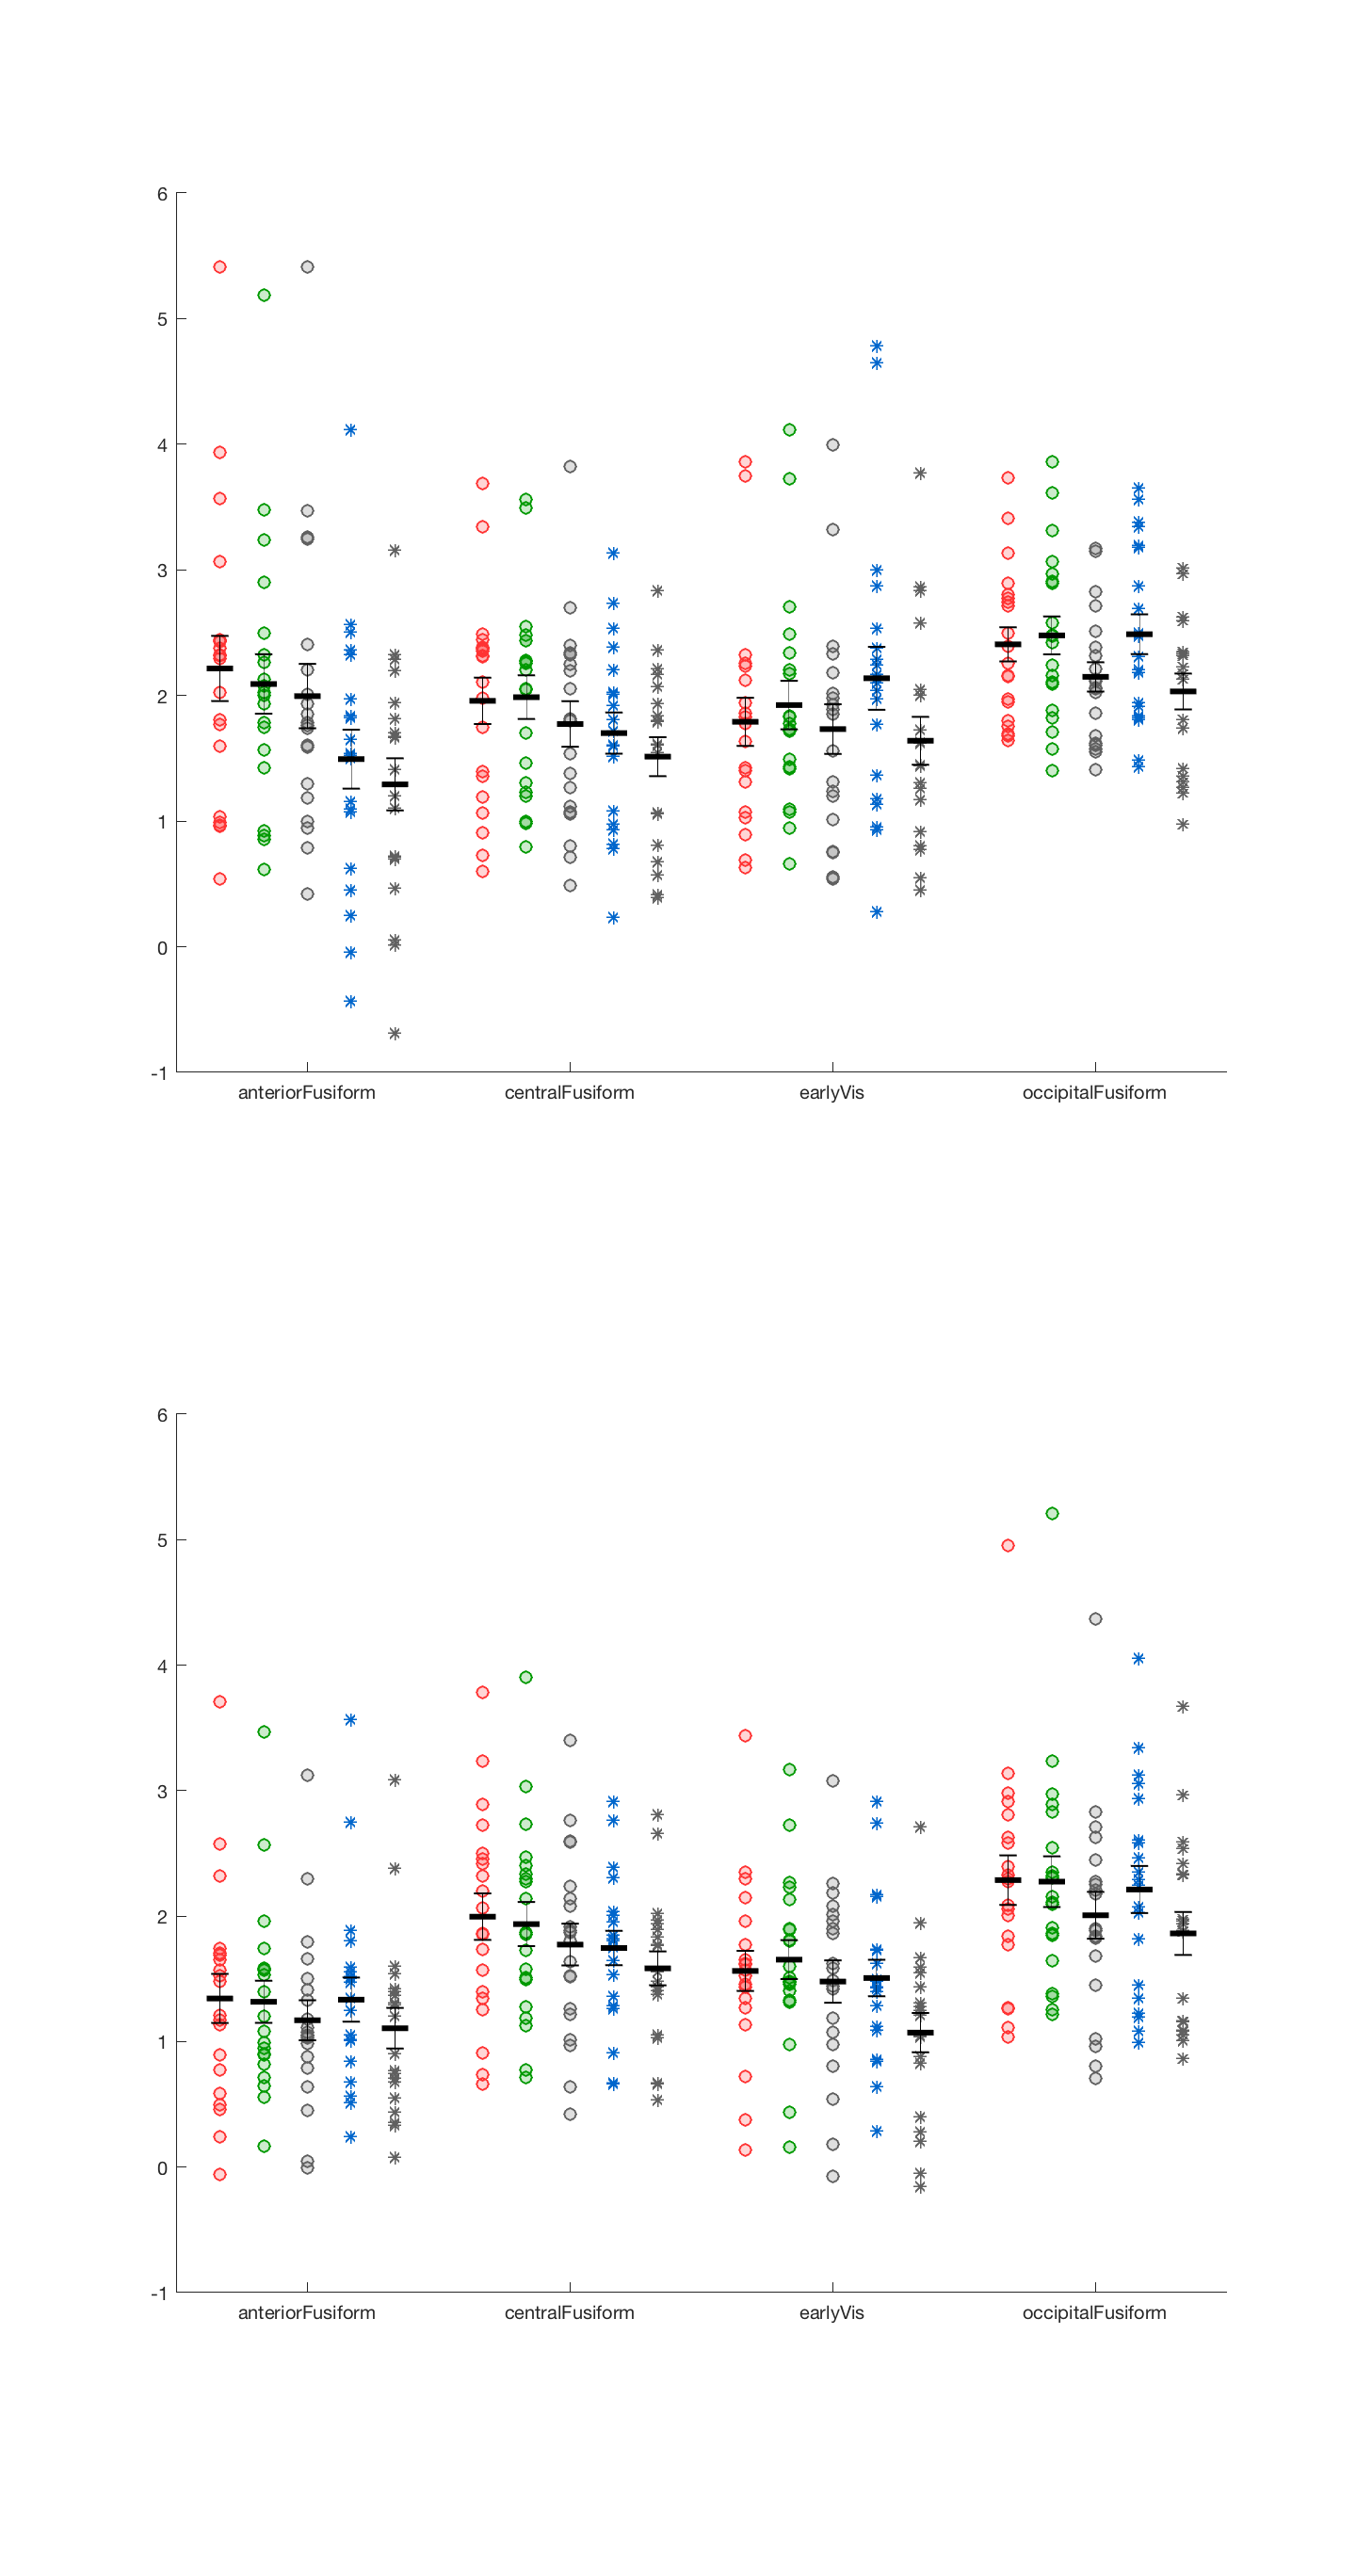

data_to_plot = megaTable_for_contrasts(:, [1:3,8,6,7,5,4]);

[g, side, rois] = findgroups(data_to_plot.Side, data_to_plot.ROI);

colors = [255 51 51; 0 153 0; 96 96 96;0 102 204; 96 96 96]./255;
markers = {'o', 'o', 'o', '*','*'};


figure ('units', 'inches')

subplot(2, 1 ,1)
xlim([0 12])
xticks([1.5 4.5 7.5 10.5])
xticklabels(rois')

x = 0:0.5:12;
x = x(mod(x,3)~=0);

means = ones(1,5*4);

for roi = 1:4
     for condition = 1:5
            x_value = (roi-1)*5+condition;
            hold on
            y = data_to_plot{g==roi, condition+3};
            meany = mean(y);
            means(x_value) = meany;
                scatter(x(x_value).* ones(20,1), y,...
                    40,markers{condition}, 'MarkerEdgeColor',colors(condition, :),...
                    'MarkerFaceColor',colors(condition, :))
                    alpha(.2)
                hold on
                plot([x(x_value)-0.15 x(x_value)+0.15],[meany meany],...
                    'Color', 'k', 'LineWidth', 3)
                hold on
                    sem=std(y)/sqrt(20);
                    CI=sem*1.96;
                    plot([x(x_value)-0.1 x(x_value)+0.1],[meany+sem meany+sem],'Color','k','LineWidth',1)
                    plot([x(x_value)-0.1 x(x_value)+0.1],[meany-sem meany-sem],'Color','k','LineWidth',1)
                    plot([x(x_value) x(x_value)],[meany-sem meany+sem],'Color','k')
            hold off
       
    end
end
subplot(2, 1 ,2)
xlim([0 12])
xticks([1.5 4.5 7.5 10.5])
xticklabels(rois')

x = 0:0.5:12;
x = x(mod(x,3)~=0);

for roi = 1:4
     for condition = 1:5
        x_value = (roi-1)*5+condition;
            hold on
            y = data_to_plot{g==roi+4, condition+3};
            meany = mean(y);
                scatter(x(x_value).* ones(20,1), y,...
                    40,markers{condition}, 'MarkerEdgeColor',colors(condition, :),...
                    'MarkerFaceColor',colors(condition, :))
                    alpha(.2)
                hold on
                plot([x(x_value)-0.15 x(x_value)+0.15],[meany meany],...
                    'Color', 'k', 'LineWidth', 3)
                hold on
                    sem=std(y)/sqrt(20);
                    CI=sem*1.96;
                    plot([x(x_value)-0.1 x(x_value)+0.1],[meany+sem meany+sem],'Color','k','LineWidth',1)
                    plot([x(x_value)-0.1 x(x_value)+0.1],[meany-sem meany-sem],'Color','k','LineWidth',1)
                    plot([x(x_value) x(x_value)],[meany-sem meany+sem],'Color','k')
            hold off
       
    end
end

set(gcf,'Units','inches','Position',[0 0 10 19])

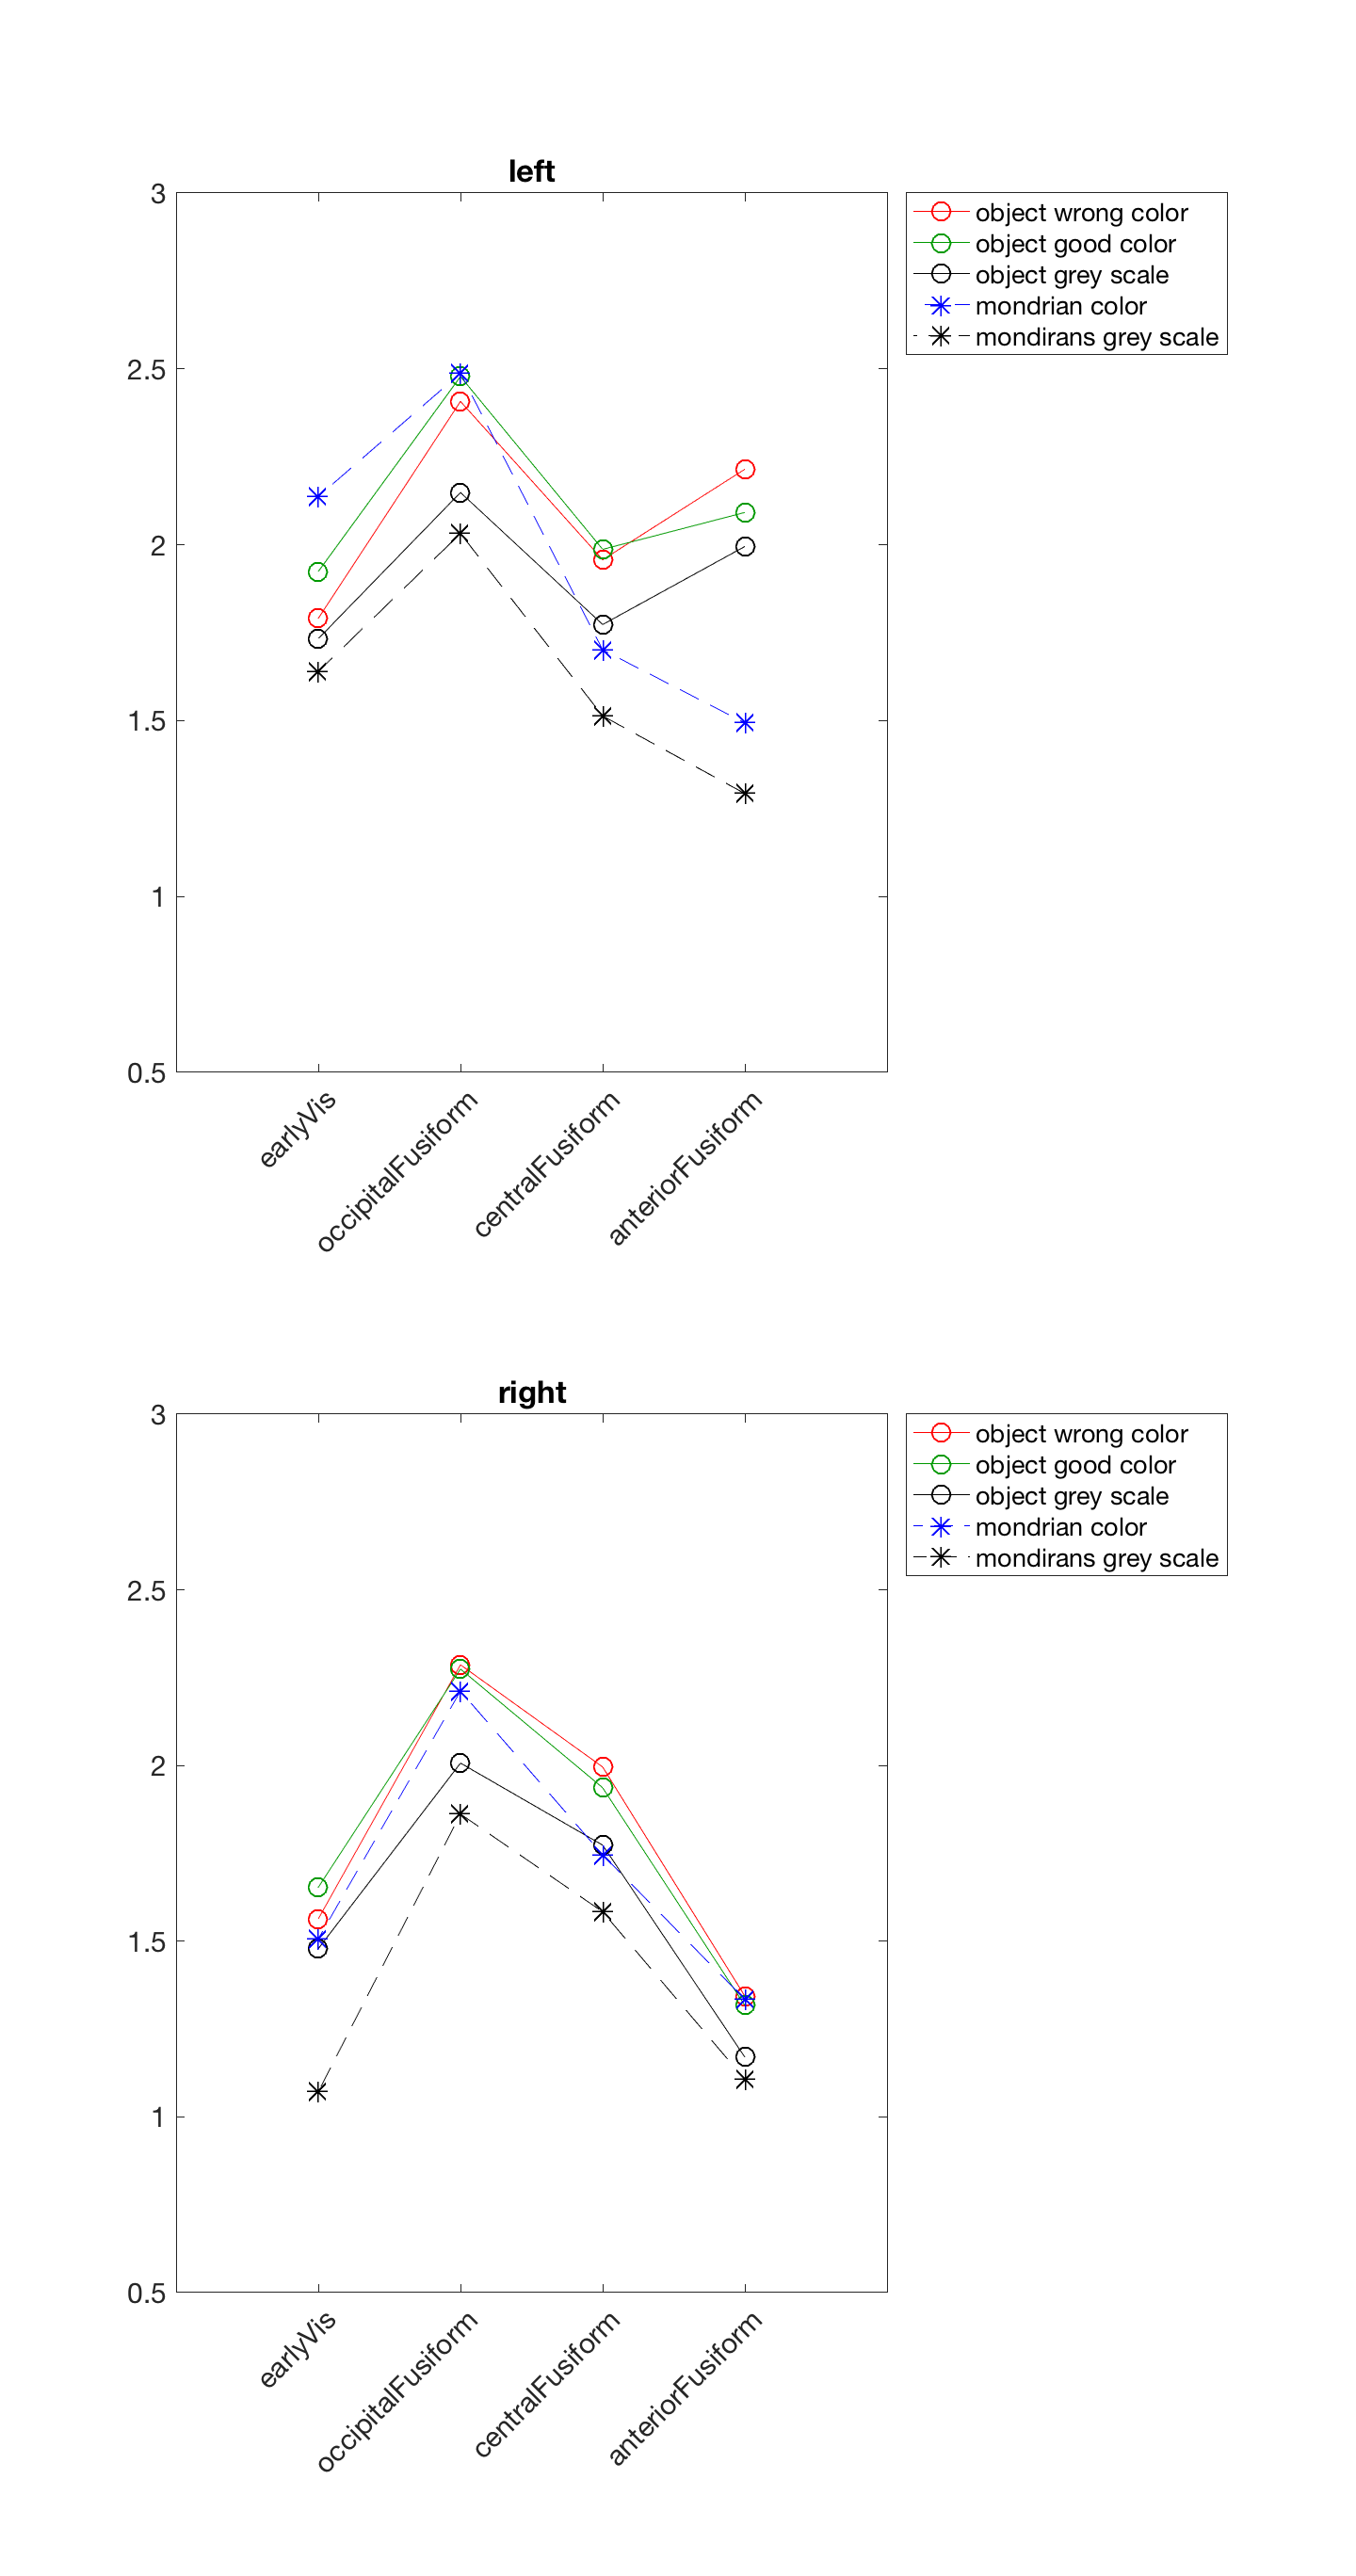

data_to_plot = megaTable_for_contrasts(:, 1:8);

[g, i1, i2] = findgroups(data_to_plot.Side, data_to_plot.ROI);
to_plot = splitapply(@mean, data_to_plot{:,4:end},g);
to_plot = to_plot([3 4 2 1 7 8 6 5], [5 3 4 2 1]);

leg = data_to_plot.Properties.VariableNames(4:end);
    leg = strrep (leg, '_', ' ');
    leg = string(leg ([5 3 4 2 1]));
    
figure('units', 'inches')
subplot(2, 1 ,1)
    h = plot(to_plot(1:4, :));
    
    set(h,{'Marker'},{'o';'o';'o'; '*'; '*'})
    set(h,'MarkerSize',10)
    set(h,{'Color'},{'r'; [0 153 0]./255; 'k';'b'; 'k' })
    set(h,{'LineStyle'},{'-';'-';'-'; '--'; '--'})

    title(i1{1} , 'fontsize',20)
    lgd = legend(leg, 'Location', 'bestoutside');
    xlim([0 5]);
    ylim ([0.5 3])
    xticks(1:1:5);
    labels = i2(1:4)';
    labels = labels([3 4 2 1]);
    xticklabels(labels);
    xtickangle(45);
    set(gca, 'FontSize', 15)

subplot (2, 1, 2)
    h = plot(to_plot(5:end, :));

    set(h,{'Marker'},{'o';'o';'o'; '*'; '*'})
    set(h,'MarkerSize',10)
    set(h,{'Color'},{'r'; [0 153 0]./255; 'k';'b'; 'k' })
    set(h,{'LineStyle'},{'-';'-';'-'; '--'; '--'})

    title(i1{5} , 'fontsize',20)
    legend(leg, 'Location', 'bestoutside');
    xlim([0 5]);
    ylim ([0.5 3])
    xticks(1:1:5);
    labels = i2(1:4)';
    labels = labels([3 4 2 1]);
    xticklabels(labels);
    xtickangle(45);
    set(gca, 'FontSize', 15)
    
set(gcf,'Units','inches','Position',[0 0 10 19])

## The shape x color interaction (bad object color vs good color and mondrian color)

%prepare data set for analysis
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 13]), 'psi1_2', 'ROI');
psi1_2 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi1_2.Properties.VariableNames(2:end) = strcat('psi1_2_', psi1_2.Properties.VariableNames(2:end));

%fir the model with firrm
objectColor2_rm = fitrm(psi1_2,'psi1_2_anteriorFusiform_left-psi1_2_occipitalFusiform_right~1',...
    'WithinDesign',contrasts_within_factors);

% run ANOVA
objectColor2_anova = ranova(objectColor2_rm, 'WithinModel','Side*ROI' )

objectColor2_anova = 8×8 table
                             SumSq     DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                            _______    __    ________    ______    __________    __________    __________    __________

    (Intercept)              8.3559     1      8.3559    21.793    0.00016747    0.00016747    0.00016747    0.00016747
    Error                    7.2849    19     0.38341                                                                  
    (Intercept):Side        0.15037     1     0.15037    3.9871       0.06038       0.06038       0.06038       0.06038
    Error(Side)             

objectColor2_margMeans_x_ROI = margmean(objectColor2_rm, 'ROI')

objectColor2_margMeans_x_ROI = 4×5 table
            ROI              Mean        StdErr      Lower       Upper  
    ___________________    _________    ________    ________    ________

    'anteriorFusiform'     -0.078726    0.066207     -0.2173    0.059847
    'centralFusiform'      -0.066029    0.048389    -0.16731    0.035251
    'earlyVis'              -0.48649     0.10032    -0.69646    -0.27653
    'occipitalFusiform'     -0.28286    0.052732    -0.39323    -0.17249


## The shape x color interaction (any object color - good or bad - vs mondrian color)

This contrast weights correspond to the situation where signals for (object good color+object bad color) - object GS are greated than signals for mondrian color vs mondrian GS. This is why the positive values of thi contrasts should be expected in object color region rather than abstract color region. 

%prepare data set for analysis
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 9]), 'psi1', 'ROI');
psi1 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi1.Properties.VariableNames(2:end) = strcat('psi1_', psi1.Properties.VariableNames(2:end));

%fir the model with firrm
objectColor_rm = fitrm(psi1,'psi1_anteriorFusiform_left-psi1_occipitalFusiform_right~1',...
    'WithinDesign',contrasts_within_factors);

% run ANOVA
objectColor_anova = ranova(objectColor_rm, 'WithinModel','Side*ROI' )

objectColor_anova = 8×8 table
                             SumSq      DF     MeanSq        F         pValue      pValueGG      pValueHF     pValueLB 
                            ________    __    ________    _______    __________    _________    __________    _________

    (Intercept)               2.4249     1      2.4249     2.8763       0.10622      0.10622       0.10622      0.10622
    Error                     16.018    19     0.84307                                                                 
    (Intercept):Side        0.054033     1    0.054033     1.1568        0.2956       0.2956        0.2956       0.2956
    Error(Side)              

The model shows a significant main effect of ROI. The main effect of side and the interaction SidexROI is not significant. 

Let's look at the effects in each ROI using marginal means:

objectColor_margMeans_x_ROI = margmean(objectColor_rm, 'ROI')

objectColor_margMeans_x_ROI = 4×5 table
            ROI              Mean        StdErr      Lower        Upper  
    ___________________    _________    ________    ________    _________

    'anteriorFusiform'     -0.055086    0.078969    -0.22037       0.1102
    'centralFusiform'       0.020847    0.062495    -0.10996      0.15165
    'earlyVis'              -0.33933     0.11622    -0.58259    -0.096075
    'occipitalFusiform'     -0.11886    0.078355    -0.28286     0.045137


To the best of my knowlegde, if the confidence intervals of a given mean include 0, it means that the simple effect is not significant at p=0.05.

Thus, we have a significant effect in the early visual cortex. Note that the value of interaction (Psi for c1) is negative, which means that this region is more tuned to mondrians than it is to object color. 

Now lets look at posthoc tests to see if there are any significant differences between the ROIs (Tuckey test)



post_hoc_objectColor_anova_ROI = multcompare(objectColor_rm,'ROI');
post_hoc_objectColor_anova_ROI(post_hoc_objectColor_anova_ROI.pValue<0.07, :)

ans = 4×7 table
          ROI_1                 ROI_2           Difference     StdErr      pValue      Lower        Upper  
    __________________    __________________    __________    ________    ________    ________    _________

    'anteriorFusiform'    'earlyVis'             0.28425      0.093999     0.03238    0.019936      0.54856
    'centralFusiform'     'earlyVis'             0.36018      0.099542    0.009069    0.080282      0.64008
    'earlyVis'            'anteriorFusiform'    -0.28425      0.093999     0.03238    -0.54856    -0.019936
    'earlyVis'            'centralFusiform'     -0.36018      0.099542    0.009069    -0.64008    -0.080282


There is a significant difference between early visual cortex ROIs and the anterior and central fusiform ROIs. The anterior and central fusiform respond more to object color than early visual ROIs (bc the difference is +). However note that there is no significant simple effect of the interaction in the anterior and central fusiform. 

## The shape effect

%prepare data set for analysis
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 10]), 'psi2', 'ROI');
psi2 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi2.Properties.VariableNames(2:end) = strcat('psi2_', psi2.Properties.VariableNames(2:end));
% fir fm model
shape_rm = fitrm(psi2,'psi2_anteriorFusiform_left-psi2_occipitalFusiform_right~1',...
    'WithinDesign',contrasts_within_factors);
%ANOVA
shape_anova = ranova(shape_rm, 'WithinModel','Side*ROI' )

shape_anova = 8×8 table
                             SumSq     DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                            _______    __    ________    ______    __________    __________    __________    __________

    (Intercept)              6.3141     1      6.3141    16.043    0.00075684    0.00075684    0.00075684    0.00075684
    Error                    7.4779    19     0.39357                                                                  
    (Intercept):Side        0.20132     1     0.20132    2.8915       0.10536       0.10536       0.10536       0.10536
    Error(Side)              1.3229

The shape model showed sigificant main effect of ROI and a significant interaction of Side x ROI. When the interaction is significant, main effect should be disregarded, so let's se the intreaction in more detail. First with marginal means:

Shape_margMeans_x_Side_by_ROI = margmean(shape_rm, 'Side_by_ROI')

Shape_margMeans_x_Side_by_ROI = 8×5 table
          Side_by_ROI            Mean        StdErr       Lower       Upper  
    _______________________    _________    ________    _________    ________

    left anteriorFusiform        0.68651     0.11433      0.44721     0.92581
    left centralFusiform         0.27947    0.050357      0.17407     0.38487
    left earlyVis              -0.090831    0.064904     -0.22668    0.045015
    left occipitalFusiform      0.061353    0.083156     -0.11269      0.2354
    right anteriorFusiform      0.043651     0.06711    -0.096813     0.18411
    right centralFusiform        0.21826    0.077904     0.055205     0.38132
    right earlyVis                0.2603    0.069042      0.11579      0.4048
    right occipitalFusiform      0.13052    0.076764    -0.030151     0.29119


There is a significant effect of shape in the left anterior fusiform, the bilateral central fusiform, and in the right early occipital ROI. All those regions show preference to object shape rather han abstract geometric figures of mondrians (the means are positive). 

Now let's look at post-hoc tests to see the relationships between ROIs. First, let's look by side:

post_hoc_shape_anova_Side_x_ROI = multcompare(shape_rm,'Side', 'by', 'ROI');
post_hoc_shape_anova_Side_x_ROI(post_hoc_shape_anova_Side_x_ROI.pValue<0.07, :)

ans = 4×8 table
           ROI            Side_1     Side_2     Difference     StdErr       pValue       Lower       Upper  
    __________________    _______    _______    __________    ________    __________    ________    ________

    'anteriorFusiform'    'left'     'right'     0.64286       0.10075    4.0412e-06     0.43198     0.85374
    'anteriorFusiform'    'right'    'left'     -0.64286       0.10075    4.0412e-06    -0.85374    -0.43198
    'earlyVis'            'left'     'right'    -0.35113      0.096157     0.0016969    -0.55239    -0.14987
    'earlyVis'            'right'    'left'      0.35113      0.096157     0.0016969     0.14987     0.55239


There is a highly significant difference between left and right anterior fusiform ROI, the left anterior fusiform shows greater preference for object shape than for mondrian shape. there is also a difference between the early occipital ROIs, wherethe right early occipital ROI seems to be more tuned towards object color than the left, where there is no shape effect. 

Now let's see by the ROIs:

post_hoc_shape_anova_Side_x_ROI = multcompare(shape_rm,'ROI','by' , 'Side');
post_hoc_shape_anova_Side_x_ROI(post_hoc_shape_anova_Side_x_ROI.pValue<0.07, :)

ans = 10×8 table
     Side             ROI_1                  ROI_2           Difference     StdErr       pValue        Lower         Upper  
    _______    ___________________    ___________________    __________    ________    __________    __________    _________

    'left'     'anteriorFusiform'     'centralFusiform'       0.40704      0.095508     0.0021845       0.13849       0.6756
    'left'     'anteriorFusiform'     'earlyVis'              0.77734        0.1319    6.1789e-05       0.40645       1.1482
    'left'     'anteriorFusiform'     'occipitalFusiform'     0.62516       0.11719    0.00020477       0.29565      0.95467
    'left'     'centralFusiform'      'anteriorFusiform'     -0.40704      0.095508  

In the left hemisphere, the anterior fusiform shows more preference towards object shape than central and occipital fusiform, and the early visual cortex. Also the central fusiform shows more object shape preference than the early visual cortex. 

In the right hemisphere however, the only differnece than reaches trend level of significance in between early occital ROI and the anterior fusiform. The early occipital ROI responds stronger to objects than the anterior fusiform. 

## Congruency effect

Last but not least, let's see if any of our ROIs differentiate between congruent or incongruent colors. Let's strat with regions that show preference towards congruent colors.

%prepare dataset
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 11]), 'psi3', 'ROI');
psi3 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi3.Properties.VariableNames(2:end) = strcat('psi3_', psi3.Properties.VariableNames(2:end));

%fit rm
congruency_rm = fitrm(psi3,'psi3_anteriorFusiform_left-psi3_occipitalFusiform_right~1',...
    'WithinDesign',contrasts_within_factors);

%run ANOVA
congruency_anova = ranova(congruency_rm, 'WithinModel','Side*ROI' )

congruency_anova = 8×8 table
                             SumSq     DF     MeanSq        F         pValue      pValueGG     pValueHF     pValueLB
                            _______    __    ________    _______    __________    _________    _________    ________

    (Intercept)              0.0264     1      0.0264    0.14712       0.70556      0.70556      0.70556     0.70556
    Error                    3.4094    19     0.17944                                                               
    (Intercept):Side        0.03499     1     0.03499     2.0579       0.16767      0.16767      0.16767     0.16767
    Error(Side)             0.32305    19    

There is a main effect of ROI and a significan Side x ROI  the interaction. Let's look at the interaction. 

Let's look at the marginal means of the interaction

Conruency_margMeans_x_Side_by_ROI = margmean(congruency_rm, 'Side_by_ROI')

Conruency_margMeans_x_Side_by_ROI = 8×5 table
          Side_by_ROI            Mean        StdErr       Lower        Upper  
    _______________________    _________    ________    _________    _________

    left anteriorFusiform       -0.12298    0.053618     -0.23521    -0.010761
    left centralFusiform        0.029627    0.037182    -0.048195      0.10745
    left earlyVis                0.13319    0.046318     0.036243      0.23013
    left occipitalFusiform      0.070703    0.067331    -0.070222      0.21163
    right anteriorFusiform     -0.026442    0.049603     -0.13026     0.077379
    right centralFusiform      -0.059113     0.03581     -0.13406      0.01584
    right earlyVis              0.089846    0.052059    -0.019114      0.19881
    right occipitalFusiform    -0.012063    0.033441    -0.082056      0

There is a significant preference towards congruent color in the letf early occipital cortex. The left anterior fusiform seems to respond more strongly to the incongruent color (negative mean).

Let's se, with post-hoc tests, if there are any cross-hemispheric differences between ROIs.

post_hoc_congruency_anova_Side_by_ROI = multcompare(congruency_rm,'Side', 'by', 'ROI');
post_hoc_congruency_anova_Side_by_ROI(post_hoc_congruency_anova_Side_by_ROI.pValue<0.07, :)

ans = 2×8 table
           ROI           Side_1     Side_2     Difference     StdErr      pValue       Lower          Upper   
    _________________    _______    _______    __________    ________    ________    __________    ___________

    'centralFusiform'    'left'     'right'     0.08874      0.042177    0.048926    0.00046251        0.17702
    'centralFusiform'    'right'    'left'     -0.08874      0.042177    0.048926      -0.17702    -0.00046251


The only significant difference is in the central fusiform ROI that responds stronger to congruent color in the left than in the right hemisphere. 

Noe, lets's look at the differences between ROIs in each hemisphere:


post_hoc_congruency_anova_ROI_by_Side = multcompare(congruency_rm,'ROI', 'by', 'Side');
post_hoc_congruency_anova_ROI_by_Side(post_hoc_congruency_anova_ROI_by_Side.pValue<0.07, :)

ans = 8×8 table
     Side            ROI_1                 ROI_2           Difference     StdErr       pValue        Lower         Upper   
    _______    __________________    __________________    __________    ________    __________    __________    __________

    'left'     'anteriorFusiform'    'centralFusiform'     -0.15261      0.051027      0.034685      -0.29609    -0.0091305
    'left'     'anteriorFusiform'    'earlyVis'            -0.25617      0.052594    0.00056583      -0.40406      -0.10829
    'left'     'centralFusiform'     'anteriorFusiform'     0.15261      0.051027      0.034685     0.0091305       0.29609
    'left'     'centralFusiform'     'earlyVis'            -0.10356      0.037341      0.05

In the left hemisphere, the anterior fusiform differs significanlty from central fusiform (no simple effect) and the early occipital ROI (preference for congruent color). The occipital ROI shows more preference towards the congruent color than the central fusiform (no simple effect). In the right hemisphere, the early occipital ROI seems to respond more to congruent than incongruent color than the cntral fusiform, but the simple effect of congruyency ni both ROIs is non-significant so this result is most likely of limited value.